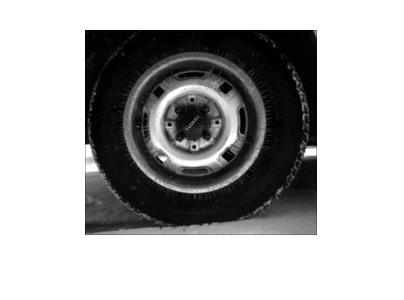

img = imread('tire.tif');
imshow(img);

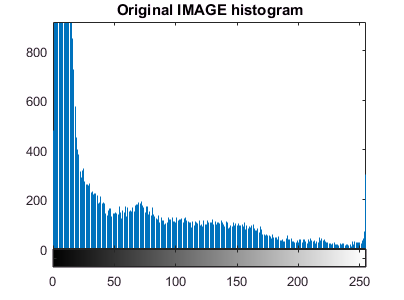

imhist(img);
title('Original IMAGE histogram');

[length,breadth] = size(img);
count = zeros(1,256);

for i = 1 : length
    for j = 1:breadth
        count(1,img(i,j)+1) = count(1,img(i,j)+1)+1;
    end
end

totalPixels = length*breadth;
pixProb = count/totalPixels;
cumFreq = zeros(1,256);
cumFreq(1,1) = pixProb(1,1);
for i = 2:256
    cumFreq(1,i) = cumFreq(1,i-1) + pixProb(1,i);
end
cumMapping = 255*cumFreq;


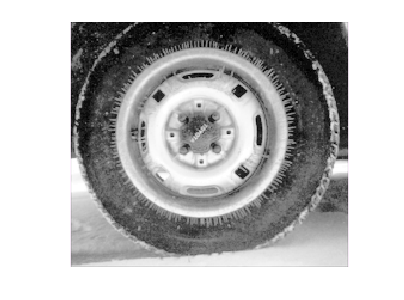

newImg = uint8(zeros(length,breadth));
for i = 1 : length
    for j = 1:breadth
        newImg(i,j) = floor(cumMapping(1,img(i,j)+1));
    end
end
imshow(newImg);

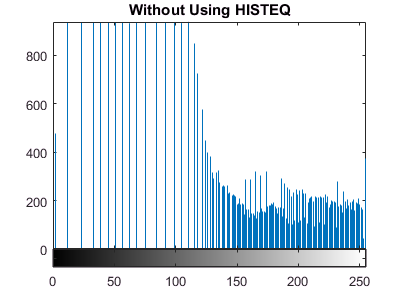

imhist(newImg);
title('Without Using HISTEQ');

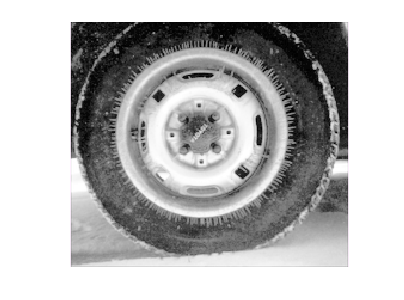

usingHisteq = histeq(img,256);
imshow(usingHisteq);

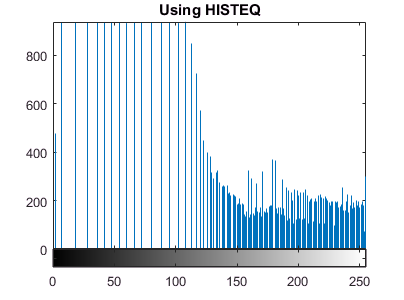

imhist(usingHisteq);
title('Using HISTEQ');